# Demo for the CocoApi (see CocoApi.m)

codel below needs to be run prior to using the API to compile the gasonMex function.

%mex('COMPFLAGS=\$COMPFLAGS -std=c++11 -Wall','-largeArrayDims','private/gasonMex.cpp','../common/gason.cpp','-I../common/','-outdir','private');
clear all

## initialize COCO api (please specify dataType/annType below)

annTypes = { 'instances', 'captions', 'person_keypoints' };
dataType='val2017'; annType=annTypes{1}; % specify dataType/annType
annFile=sprintf('../../annotations/%s_%s.json',annType,dataType);
coco=CocoApi(annFile);

Loading and preparing annotations... DONE (t=0.61s).


## display COCO categories and supercategories

if( ~strcmp(annType,'captions') )
  cats = coco.loadCats(coco.getCatIds());
  nms={cats.name}; fprintf('COCO categories: ');
  fprintf('%s, ',nms{:}); fprintf('\n');
  nms=unique({cats.supercategory}); fprintf('COCO supercategories: ');
  fprintf('%s, ',nms{:}); fprintf('\n');
end

COCO categories: 

person, bicycle, car, motorcycle, airplane, bus, train, truck, boat, traffic light, fire hydrant, stop sign, parking meter, bench, bird, cat, dog, horse, sheep, cow, elephant, bear, zebra, giraffe, backpack, umbrella, handbag, tie, suitcase, frisbee, skis, snowboard, sports ball, kite, baseball bat, baseball glove, skateboard, surfboard, tennis racket, bottle, wine glass, cup, fork, knife, spoon, bowl, banana, apple, sandwich, orange, broccoli, carrot, hot dog, pizza, donut, cake, chair, couch, potted plant, bed, dining table, toilet, tv, laptop, mouse, remote, keyboard, cell phone, microwave, oven, toaster, sink, refrigerator, book, clock, vase, scissors, teddy bear, hair drier, toothbrush, 


COCO supercategories: 

accessory, animal, appliance, electronic, food, furniture, indoor, kitchen, outdoor, person, sports, vehicle, 


## get all images containing given categories, select one at random

catIds = coco.getCatIds('catNms',{'person','bird'});
imgIds = coco.getImgIds('catIds',catIds);
catIds = coco.getCatIds('catNms', {'person','elephant'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));

catIds = coco.getCatIds('catNms', {'person','horse'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));
catIds = coco.getCatIds('catNms', {'person','sheep'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));
catIds = coco.getCatIds('catNms', {'person','cow'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));
catIds = coco.getCatIds('catNms', {'person','bear'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));
catIds = coco.getCatIds('catNms', {'person','zebra'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));
catIds = coco.getCatIds('catNms', {'person','giraffe'});
imgIds = union(imgIds, coco.getImgIds('catIds',catIds));


## load and display random image

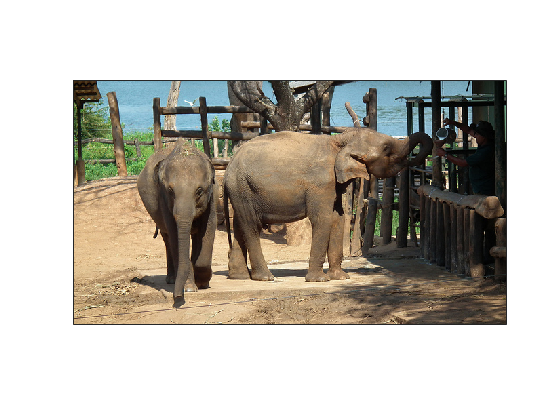

imgId = imgIds(randi(length(imgIds)));
img = coco.loadImgs(imgId);
I = imread(sprintf('../../images/%s/%s',dataType,img.file_name));
figure(1); imagesc(I); axis('image'); set(gca,'XTick',[],'YTick',[])

## load and display annotations

annIds = coco.getAnnIds('imgIds',imgId,'catIds',catIds,'iscrowd',[]);
anns = coco.loadAnns(annIds); coco.showAnns(anns);